# Try different index for winner-take-all

clear;
clc;
addpath('..\funcs');
load ..\..\data\all_0_0.5_0_0.05_Iattn_0.02.mat;
load ..\..\data\allpsd_0_0.5_0_0.05_Iattn_0.02.mat;
levelSheet = levelSheet*1000;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 10;
steps = size(levelSheet,1);
pop = 5;

## rule out

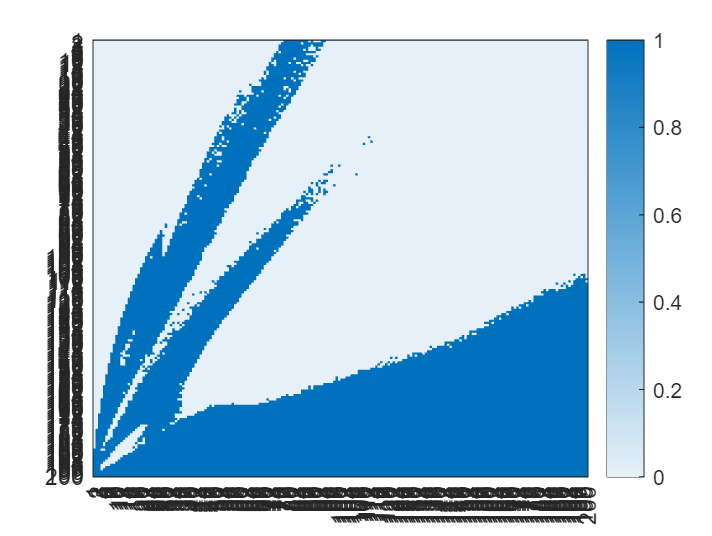

ruleOut = zeros(steps,steps);

% huge difference between conds
maxratio = 3;
for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        maxLevel = max([cond0 cond1 cond2 cond3 cond4 cond5]);
        if cond0*maxratio<maxLevel || cond1*maxratio<maxLevel || cond2*maxratio<maxLevel || cond3*maxratio<maxLevel || cond4*maxratio<maxLevel || cond5*maxratio<maxLevel
            ruleOut(i,j) = 1;
        end
    end
end
figure();
heatmap(ruleOut);
grid off;


% too many peaks in psd


## see peaks in psd

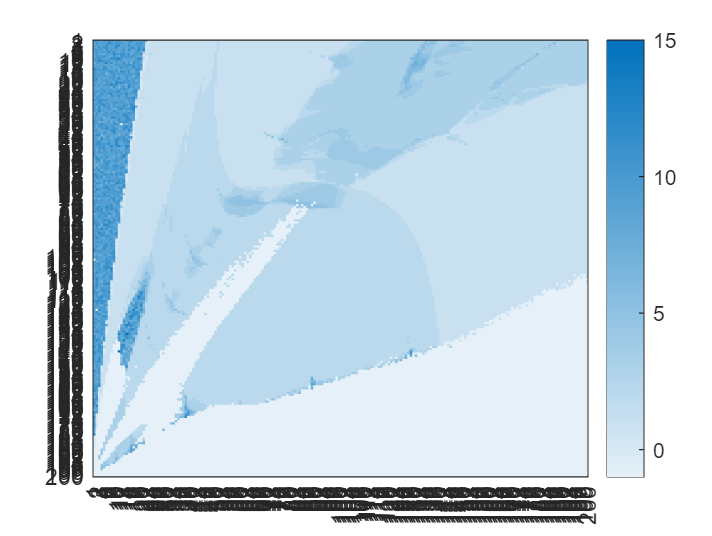

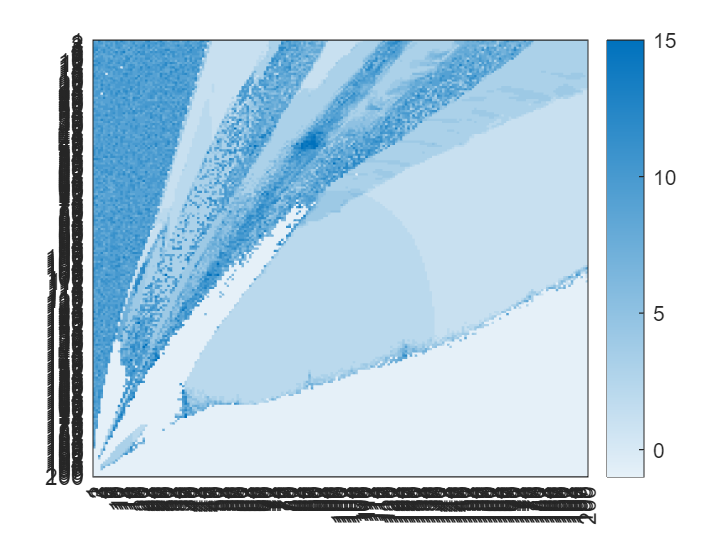

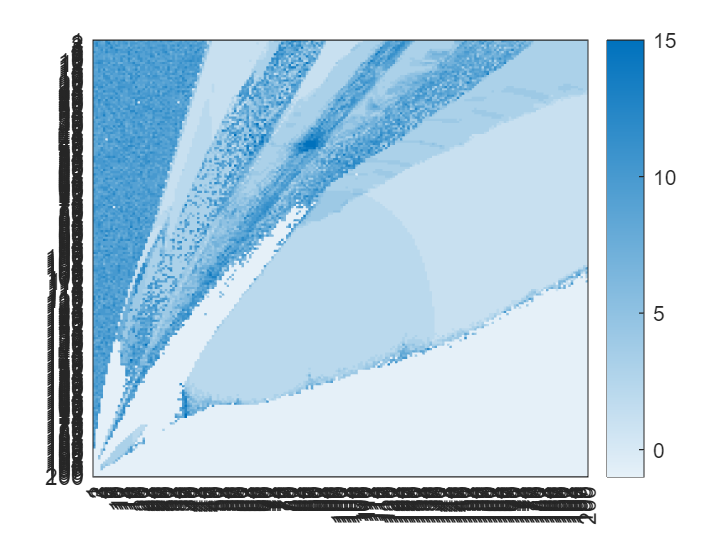

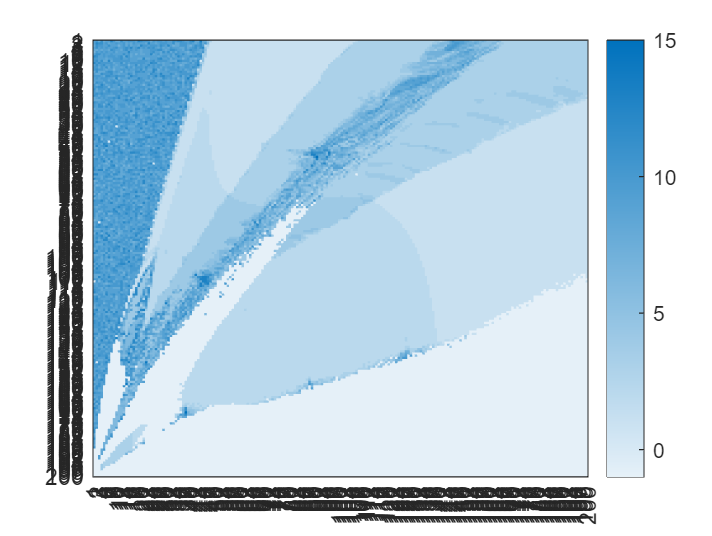

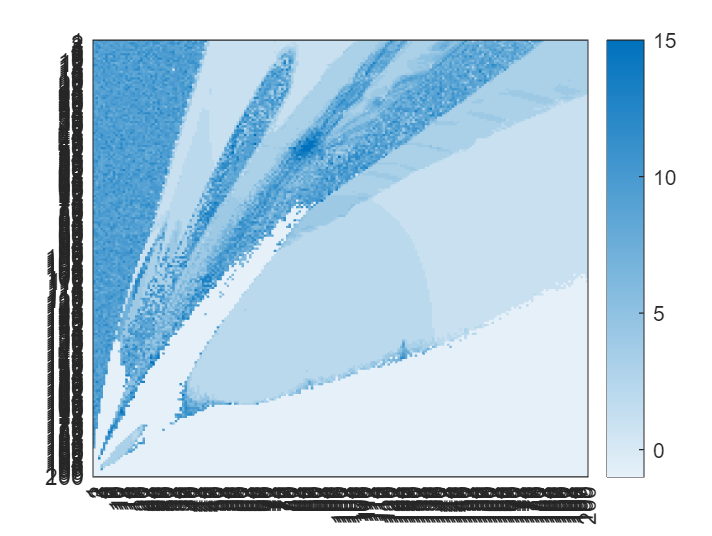

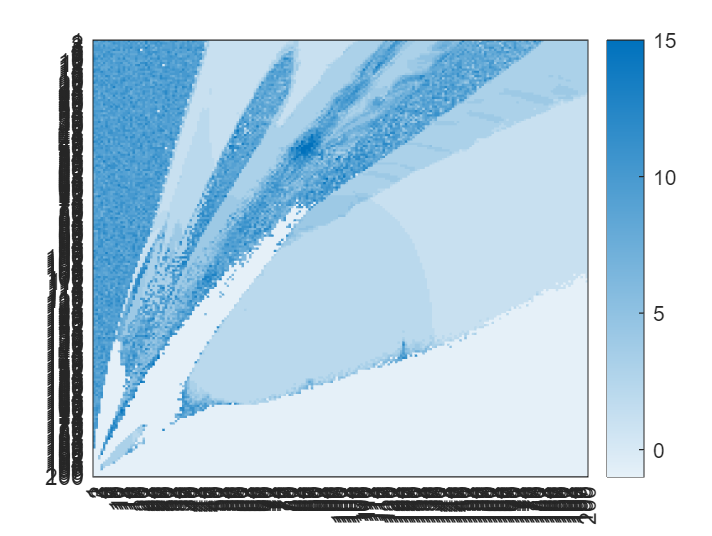

for cond = 1:6
psdPeaks = squeeze(psdPeaksSheet(:,:,pop,cond));
figure();
title(append(""));
heatmap(psdPeaks);
grid off;
end

%% 

## Envelop of firing rate

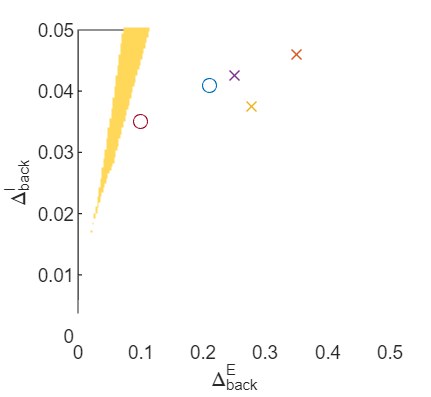

anti_WTA_sens = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,pop,2) < levelSheet(i,j,pop,3)
            anti_WTA_sens(i,j) = 1;
        end
    end
end

anti_WTA_attn = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,pop,5) < levelSheet(i,j,pop,6)
            anti_WTA_attn(i,j) = 1;
        end
    end
end

anti_WTA_sens = anti_WTA_sens == 1;
anti_WTA_attn = anti_WTA_attn == 1;

figure();
for i = 1:steps
    x = Delta_e(anti_WTA_sens(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end

for i = 1:steps
    x = Delta_e(anti_WTA_attn(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ffd859"); % yellow
    hold on;
end

anti_WTA_both = anti_WTA_sens .* anti_WTA_attn;
anti_WTA_both = anti_WTA_both == 1;
for i = 1:steps
    x = Delta_e(anti_WTA_both(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#293253"); % dark blue
    hold on;
end

% STY-STY
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= -1 && sum(osciSheet(i,j,5,2:6)==1)<5
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white: stationary
    hold on
end

% Chaos
for i = 1:steps
    x = Delta_e(chaos(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % Red: chaos
    hold on
end

% sample points
scatter(0.1, 0.035, 'o'); % y
scatter(0.21, 0.041, 'o'); % y
scatter(0.35, 0.046, 'x'); % g
scatter(0.2775, 0.0375, 'x'); % g
scatter(0.25, 0.0425, 'x'); % g


xlabel("\Delta_{back}^{E}");
ylabel("\Delta_{back}^{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
box on;
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
hold off;

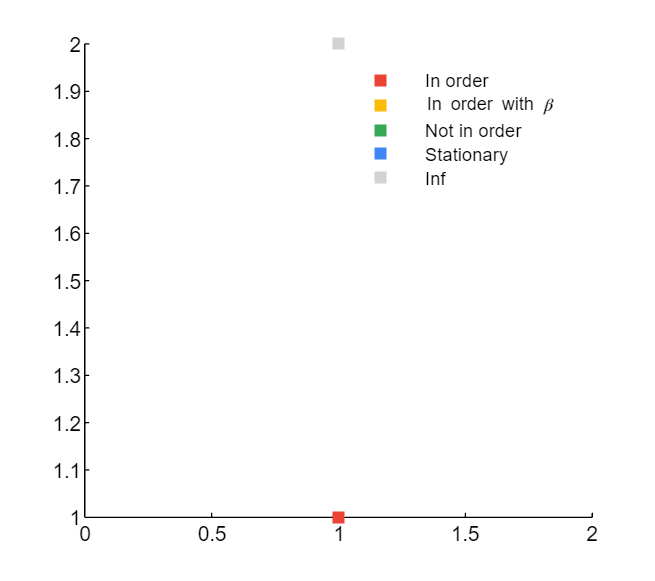

figure()
s1 = scatter(1,1,'s','filled',"MarkerFaceColor","#EA4335"); % red
hold on
s2 = scatter(1,2,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
s3 = scatter(1,2,'s','filled',"MarkerFaceColor","#34A853"); % green
s4 = scatter(1,2,'s','filled',"MarkerFaceColor","#4285F4"); % blue
s5 = scatter(1,2,'s','filled',"MarkerFaceColor",[209 211 212]/256); % grey
whitebg([1 1 1]);

lgd = legend([s1 s2 s3 s4 s5],["In order", "In order with \beta","Not in order", "Stationary","Inf"]);
legend boxoff  
lgd.FontName = 'Arial';
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
x0 = 0; y0 = 0; width = 9; height = 8;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);

% print('planeLegend', '-dpng', '-r600');
% print('planeLegend', '-dsvg', '-r600');
% print('planeLegend', '-dpdf', '-r600');

## anti-WTA-attn: yellow

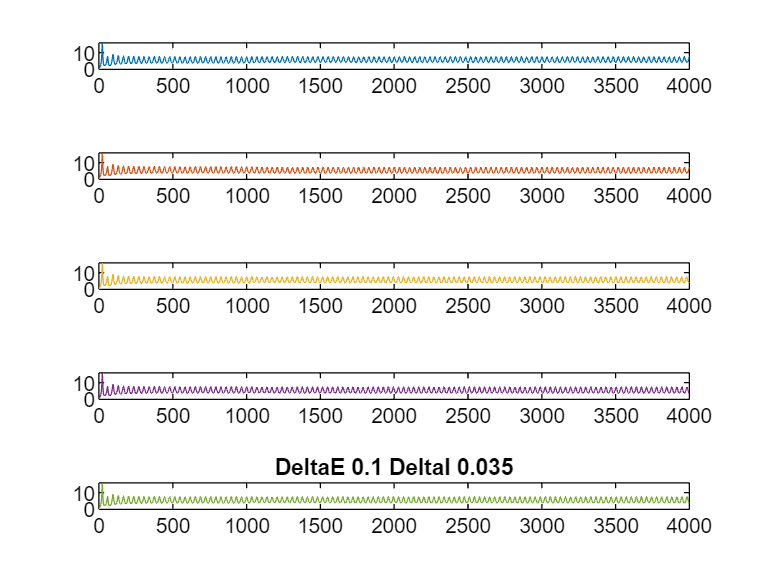

pop = 5;
dt = 0.01;
time = 4000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.1;
DeltaI = 0.035;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];
title(filename);
hold off;

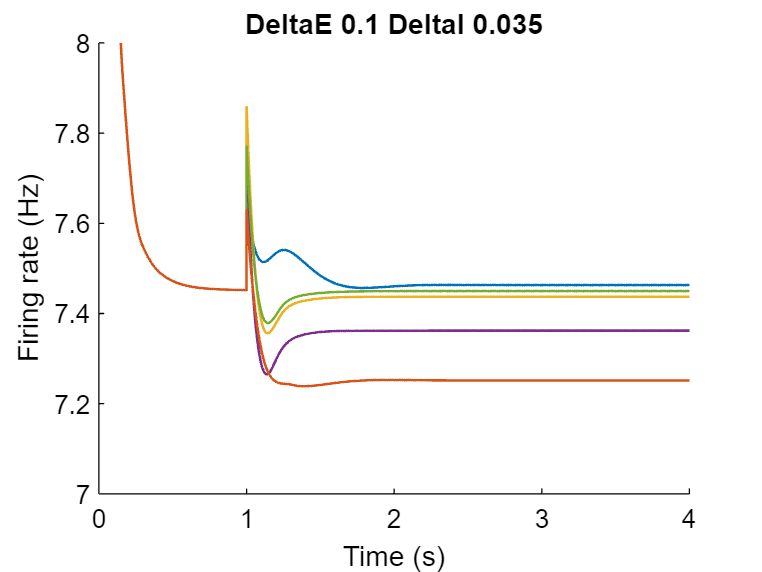


figure();
hold on;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

title(filename);

axis([0 4 7 8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

## anti-WTA-attn: yellow

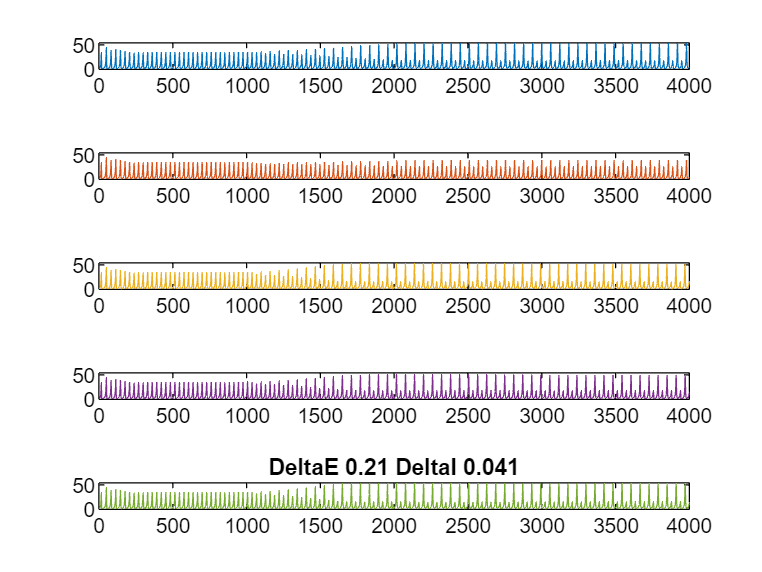

pop = 5;
dt = 0.01;
time = 4000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.21;
DeltaI = 0.041;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];
title(filename);
hold off;

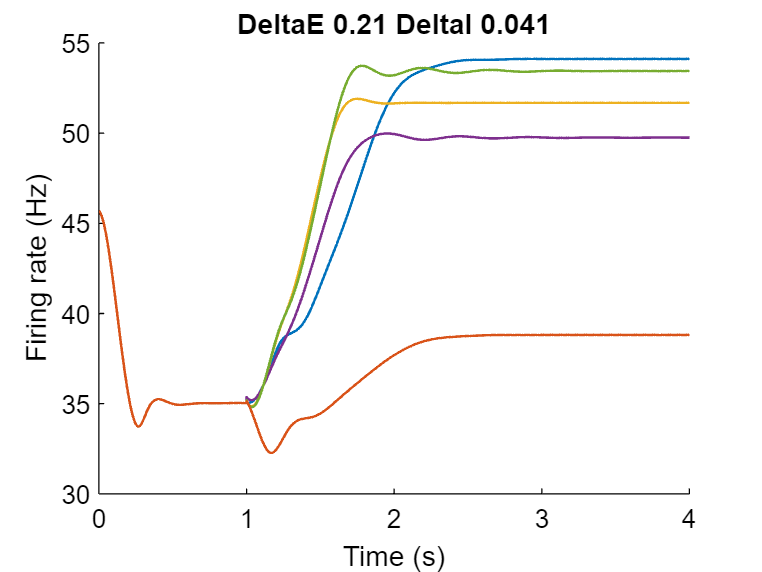


figure();
hold on;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

title(filename);

% axis([0 4 7 8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

## anti-WTA-sens: green

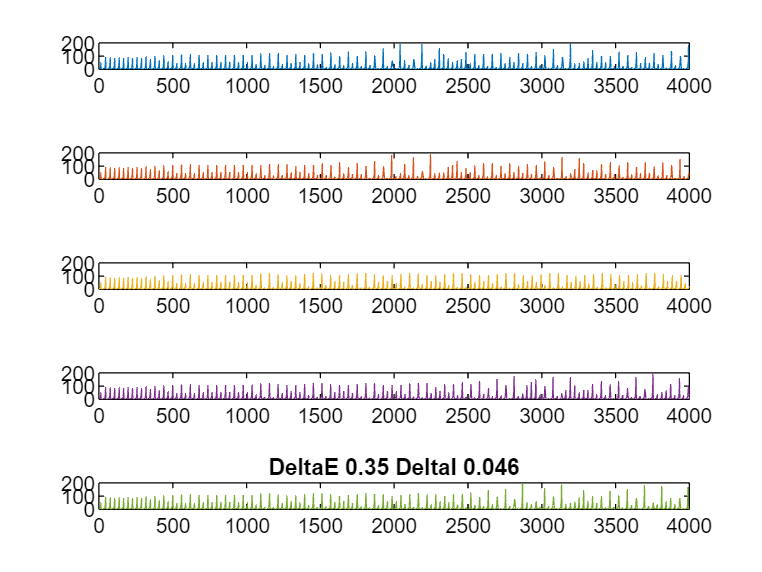

pop = 5;
dt = 0.01;
time = 4000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.35;
DeltaI = 0.046;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];
title(filename);
hold off;

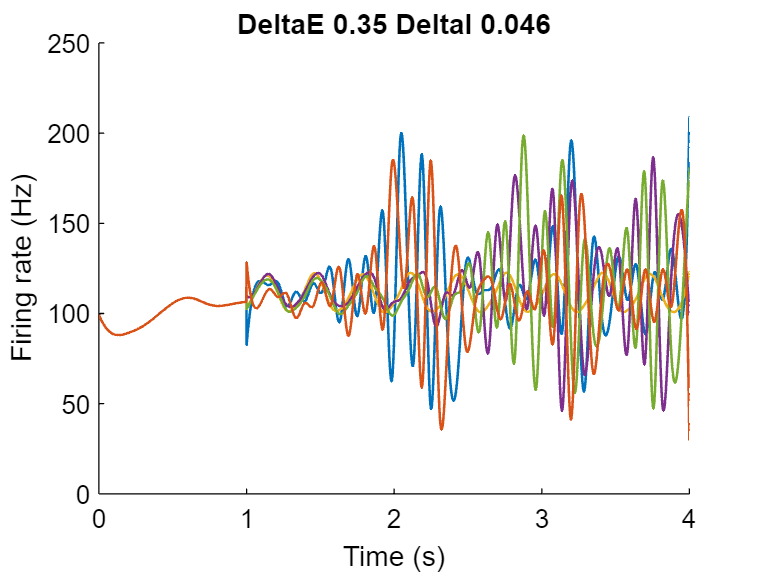


figure();
hold on;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

title(filename);

% axis([0 4 7 8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

## anti-WTA-sens: green

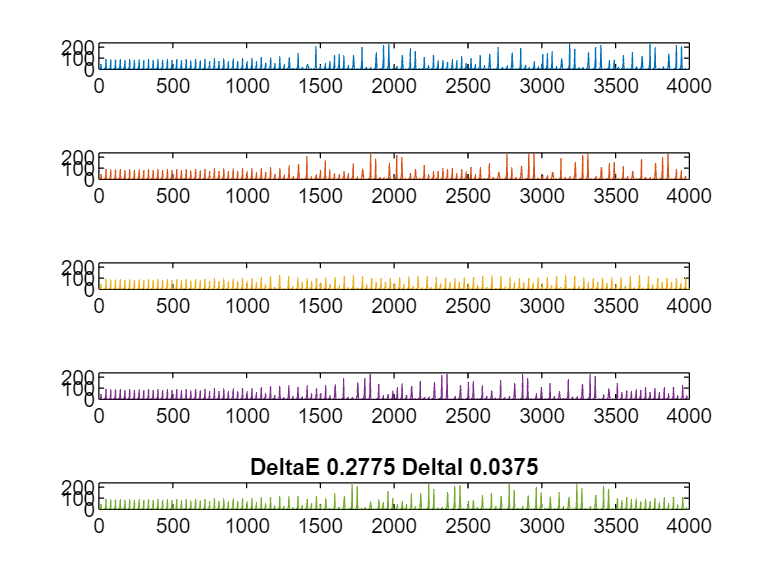

pop = 5;
dt = 0.01;
time = 4000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.2775;
DeltaI = 0.0375;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];
title(filename);
hold off;

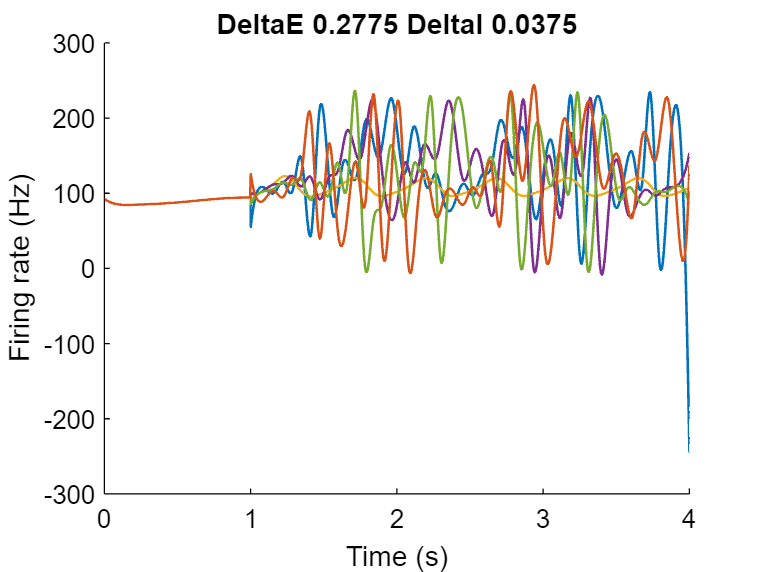


figure();
hold on;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

title(filename);

% axis([0 4 7 8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

## anti-WTA-sens: green

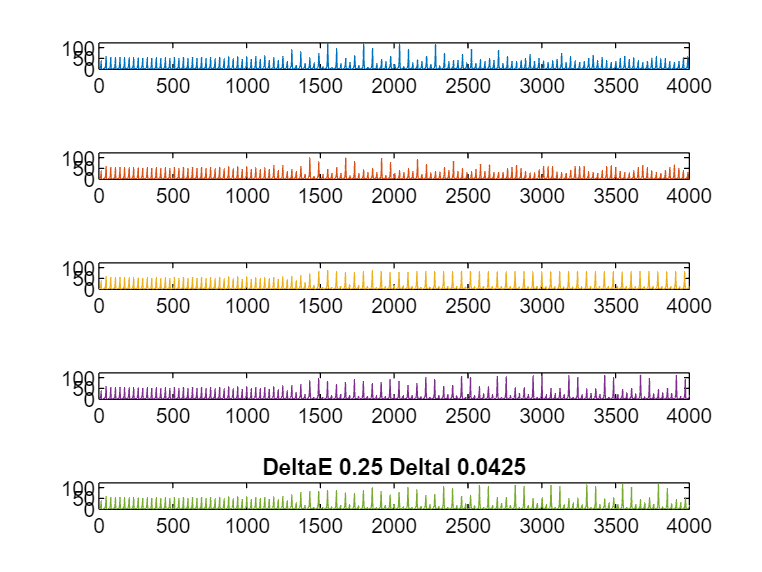

pop = 5;
dt = 0.01;
time = 4000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.25;
DeltaI = 0.0425;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];
title(filename);
hold off;

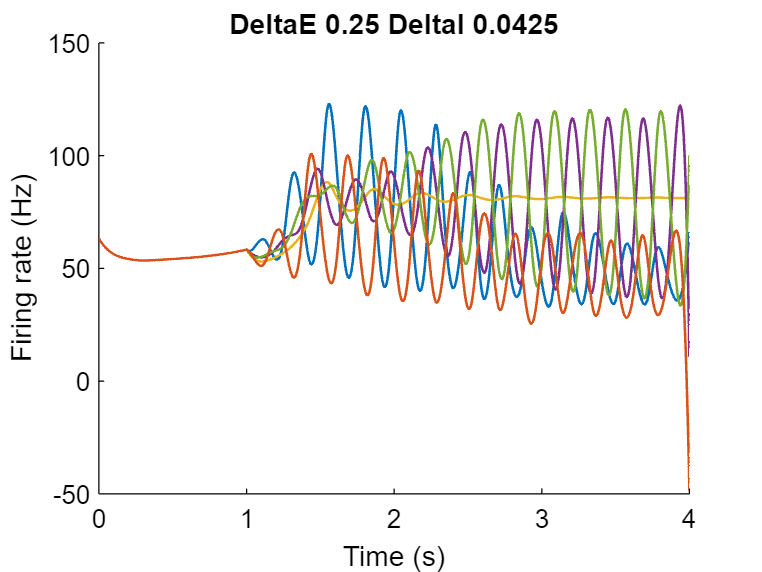


figure();
hold on;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

title(filename);

% axis([0 4 7 8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

## anti-WTA both: dark blue